# Homework 13

## [✔] ADSI Problem 7.1

A tremendous amount of functionality is found in MATLABs toolboxes and Hilbert transforms are no exception. Type doc hilbert in MATLAB and read the documentation.  

doc hilbert

## [✔] ADSI Problem 7.2: Hilbert transform of a cosine signal

*A continuous time signal is given by *$x\left(t\right)=4+3\mathrm{cos}\left(\omega t\right)$*. What is the Hilbert transform of this signal?  *

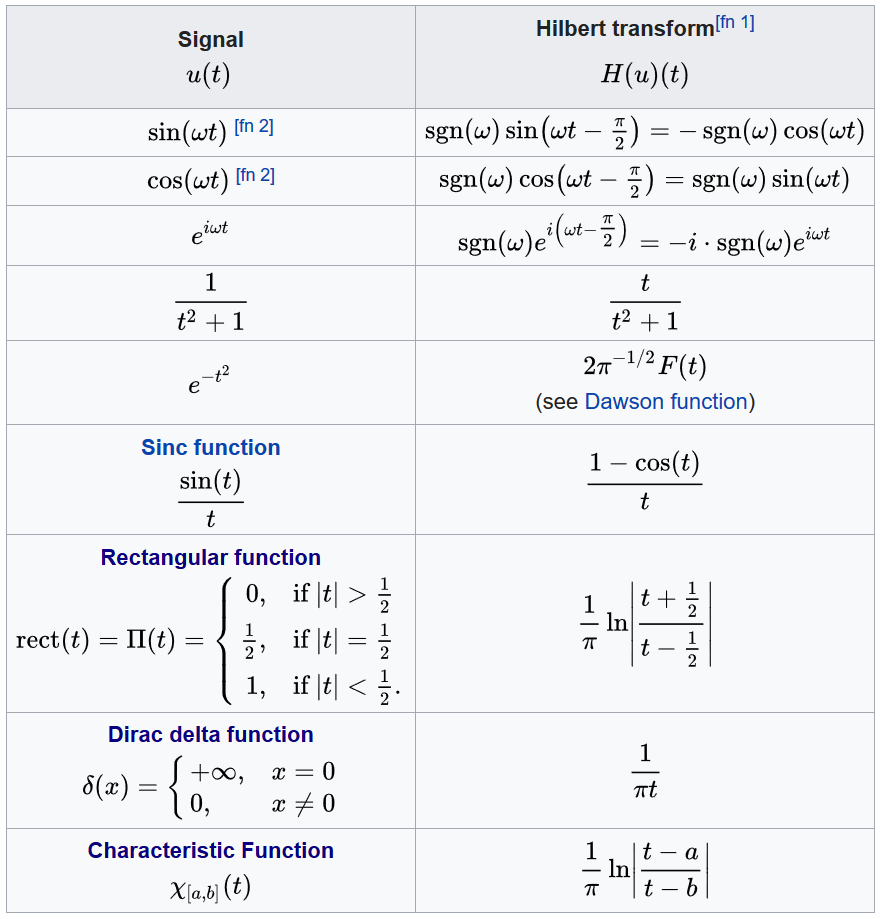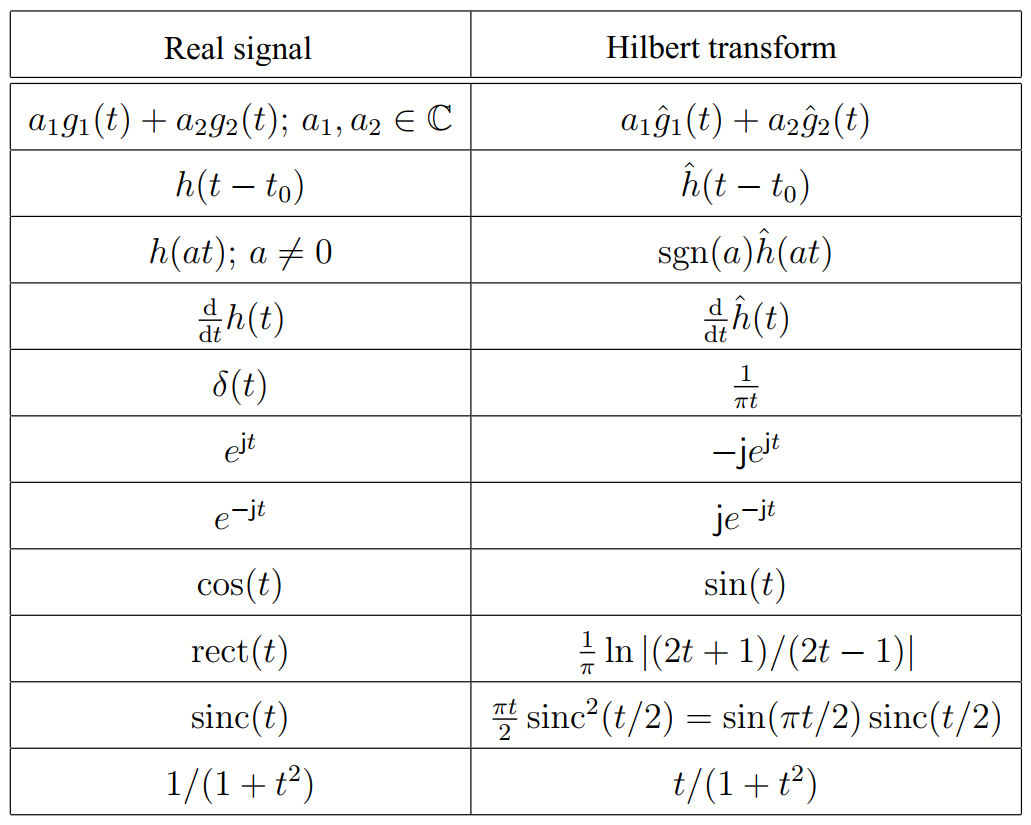


$$H\left\lbrack 4+3\;\mathrm{cos}\left(\omega t\right)\right\rbrack =H\left\lbrack 4\right\rbrack +3H\left\lbrack \mathrm{cos}\left(\omega t\right)\right\rbrack$$



$$H\left\lbrack 4+3\;\cos \left(\omega t\right)\right\rbrack =0+3\mathrm{sgn}\left(\omega \right)\mathrm{sin}\left(\omega t\right)$$
 

## [✔] ADSI Problem 7.3: One-sided spectrum of analytical signals

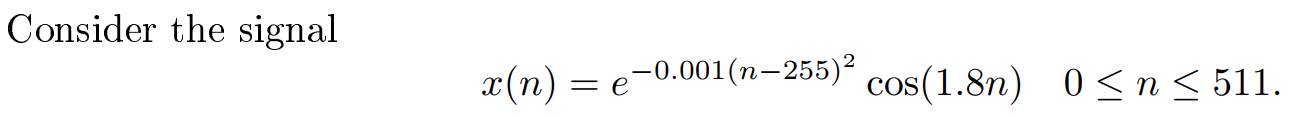

*Calculate the analytical signal in MATLAB and check that the spectrum is one-sided as expected.  *

Recall that we start with a real-valued signal $x_r \left(t\right)$ and we want we need to represent the signal as a complex sinusoid:

        
$$x_c \left(t\right)=x_r \left(t\right)+j\;x_i \left(t\right)$$


$x_c \left(t\right)$ is known as an ***analytic signal*** because it has no negative-frequency spectral components.

To show that the spectrum is one-sided, we have to show that the frequency response $X_c \left(e^{j\omega } \right)$ is zero over the negative frequency range. 

We can do this by estimating the power spectrum density (PSD) of the analytical signal using the periodogram.

In the MATLAB plot, the normalised **positive frequency range** is [0, 1] whereas the **negative frequency range** is between 1 and 2. Notice there is no power spikes in the negative frequency range, only noise.

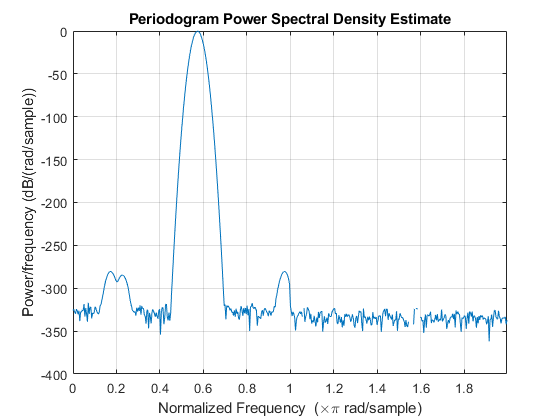

n = (0:511)';
x = exp(-0.001.*(n-225).^2).*cos(1.8*n);

% Compute the analytic signal of the real signal x(n)
y = hilbert(x);

% Compute and plot the PSD estimate
periodogram(y)

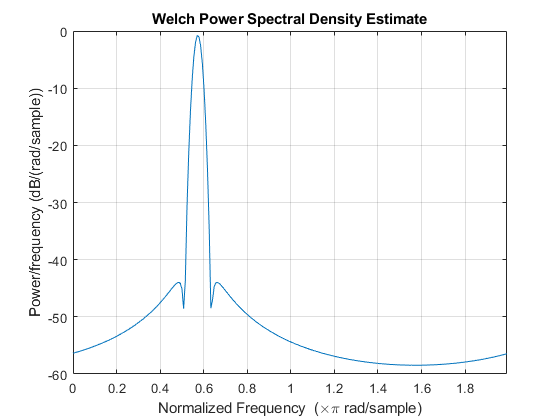

% PSD estimate using the Welch method
pwelch(y)

## [✔] ADSI Problem 7.4: Swept sine wave

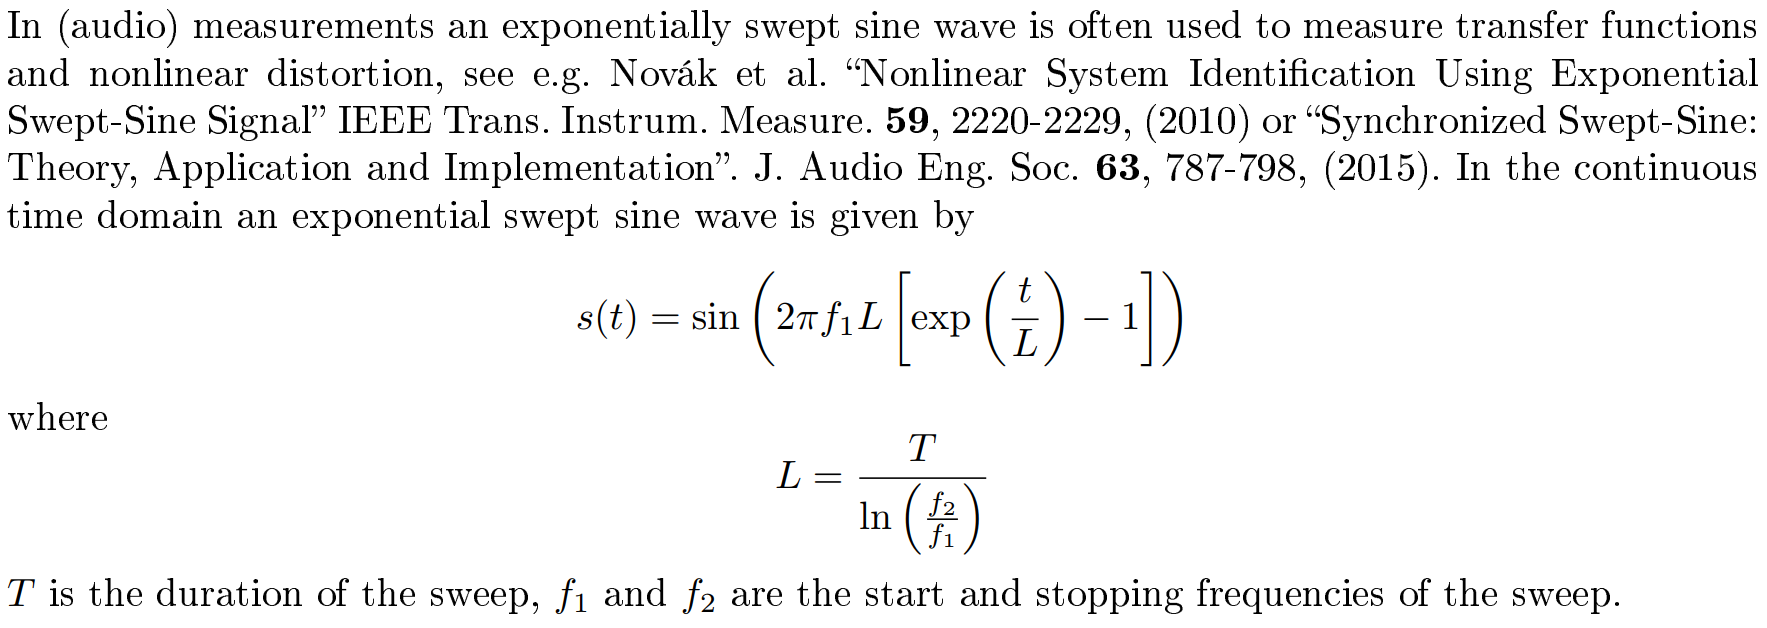

clear variables;

### [✔] 1. Design swept sine signal

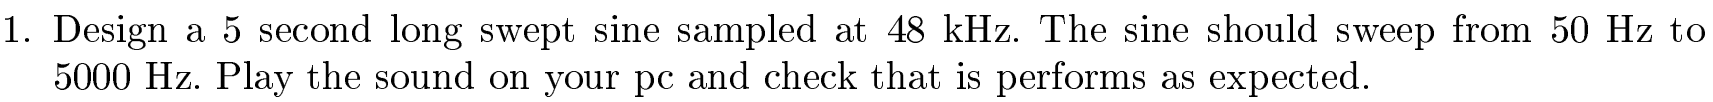

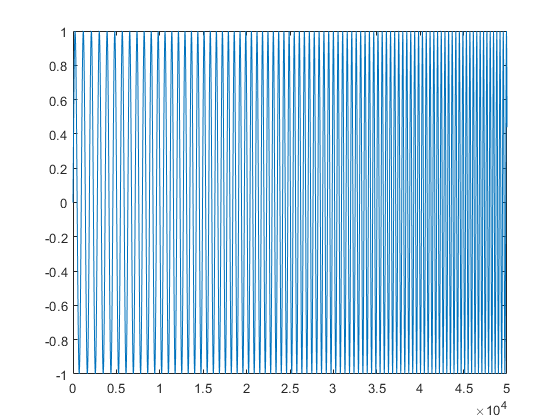

Ts = 48000;  % Sampling rate
f1 = 50;     % Starting 1/frequency
f2 = 5000;   % Stopping 1/frequency
T = 5*Ts;    % Duration of the sweep
L = T / log(f2/f1);

n = 0:T-1;
s = sin(2*pi * f1 * L * (exp(n/L) - 1) / Ts);

% Write to file 
% audiowrite('swept_sine.wav', s, Ts);

% Play sound
soundsc(s, Ts);

% Plot it
plot(n, s)
xlim([0, 50000]);

### [✔] 2. Compute instantaneous frequency

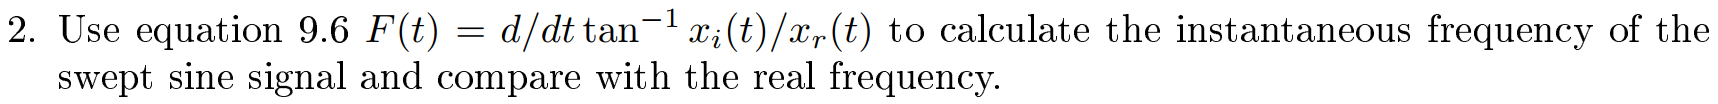

        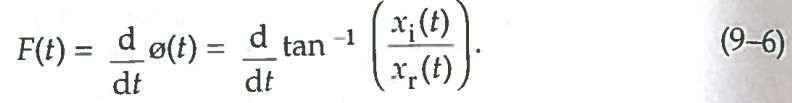

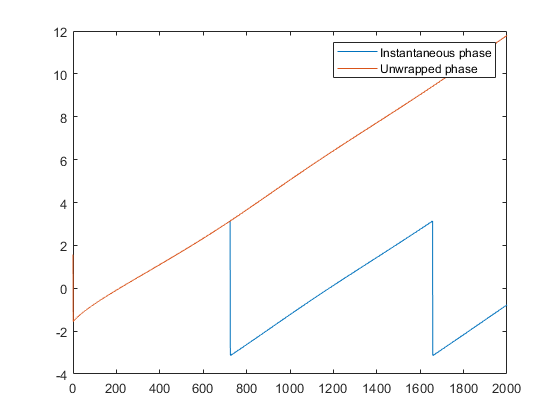

s_c = hilbert(s);  % Compute the analytic signal

% The instantaneous phase can be computed using MATLAB's angle function
inst_phase = angle(s_c);
plot(n, inst_phase, n, unwrap(inst_phase))
legend('Instantaneous phase', 'Unwrapped phase')
xlim([0, 2000])

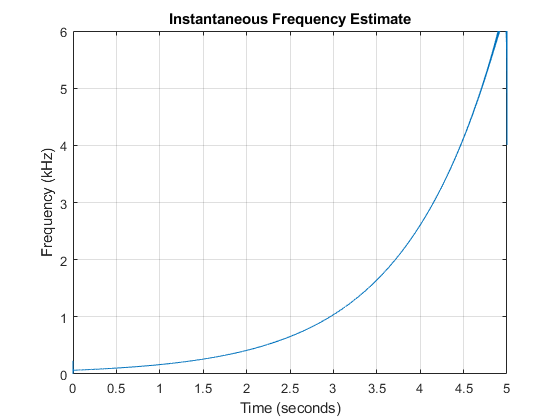

% Approximate the derivative of the unwrapped instantaneous phase
F = diff(unwrap(inst_phase));

% Plot it
plot(n(2:end)/Ts, F*10)
ylim([0, 6])
grid on
ylabel('Frequency (kHz)')
xlabel('Time (seconds)')
title('Instantaneous Frequency Estimate')

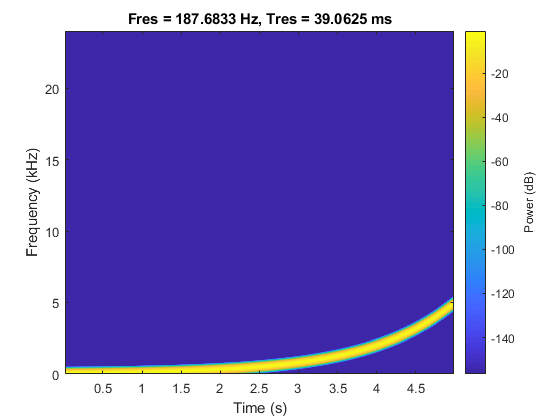

% Estimate the spectrogram of the waveform using the pspectrum function. 
pspectrum(s, Ts, 'spectrogram')

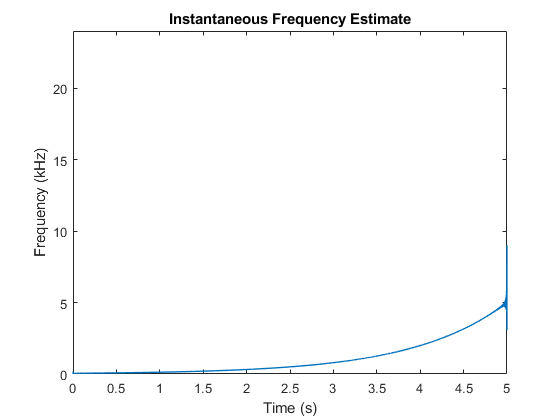


% The instfreq function computes and displays the instantaneous frequency in one step.
instfreq(s, Ts, 'Method', 'hilbert')

## [?] ADSI Problem 7.5: Envelope Detection

*The textbook states that the Hilbert transform can be used to find the envelope of a signal. The validity of this statement is investigated in this problem. *

*Consider an exponentially decaying oscillating signal given by*

        
$$x\left(n\right)=4e^{-0\ldotp 01n} \mathrm{cos}\left(\pi n\right)$$


clear variables;
clf

### [?] 1. Plot the signal and envelope on the same graph

*Plot this signal and use equation 9.4 to plot the envelope on the same graph. Compare the result with the expected outcome.*

The books states: If a real sinewave $x_r \left(t\right)$ is amplitude modulated so its envelope contains information, then we can measure the instantaneous envelope $E\left(t\right)$ values from an analytic version of the signal using the Equation 9-4:

        

Equation 9-4 states that the envelope of the signal is equal to magnitude of $x_c \left(t\right)$.

In MATLAB the complex magnitude of a signal can be computed with the `abs` function. 

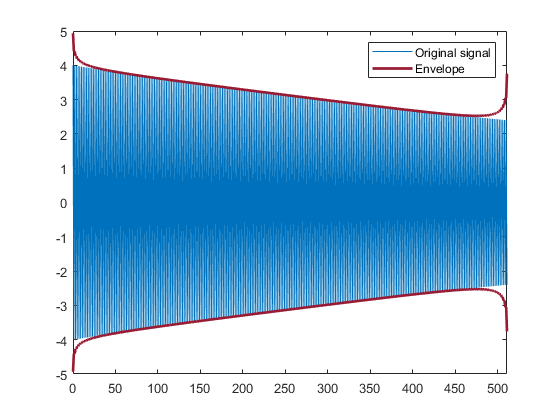

n = (0:511);
x_r = 4*exp(-0.001.*n).*cos(pi*n);

% Compute the analytic signal
x_c = hilbert(x_r);

% Find the envelope by computing the magnitude of the signal
x_envelope = abs(x_c);

% Plot the real signal
plot(n, x_r)
hold on

% Plot the envelope
plot(n, [-1;1]*x_envelope, 'Color', [0.6 0.1 0.2],'Linewidth',2)
hold off

legend('Original signal', 'Envelope')
xlim([0, max(n)])

[?] I expected the envelope to be smooth over the whole range. However, it seems that envelope around the edges are off slight. Why is that?

### [✔] 2. Describe how noise affects Hilbert transform's ability to recover the envelope

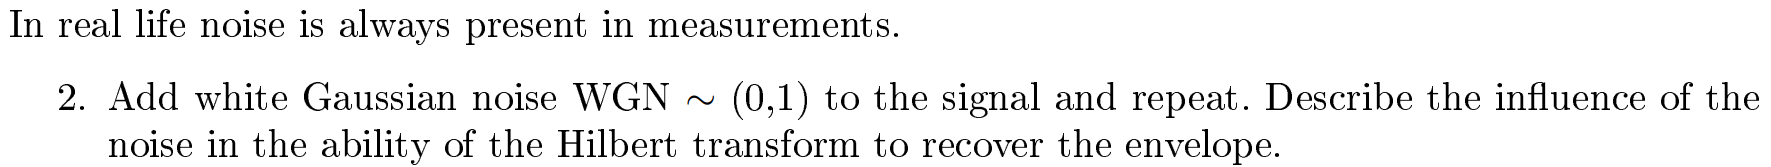

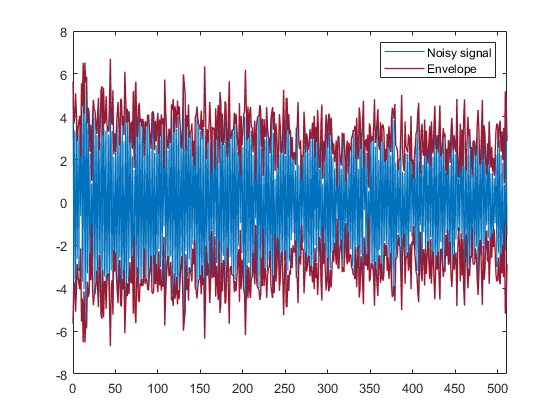

N = 512;
n = (0:N-1);
w = randn(N, 1)';
x_r = 4*exp(-0.001.*n).*cos(pi*n) + w;

x_c = hilbert(x_r);
x_envelope = abs(x_c);

plot(n, x_r)
hold on
plot(n, [-1;1]*x_envelope, 'Color', [0.6 0.1 0.2],'Linewidth',1)
hold off
legend('Noisy signal', 'Envelope')
xlim([0, max(n)])

Hilbert transform is sensitive to noise. We observe spurious peaks in the envelope due to noise.

We can generate a moving Root-Mean-Square (RMS) average envelopes by using a sliding window of size $W$. Using a large window size smooths out the envelope.

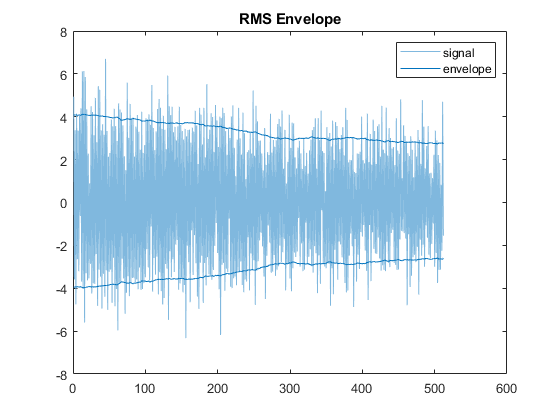

envelope(x_r, 100, 'rms');

### [✔] 3. Try with other two signals

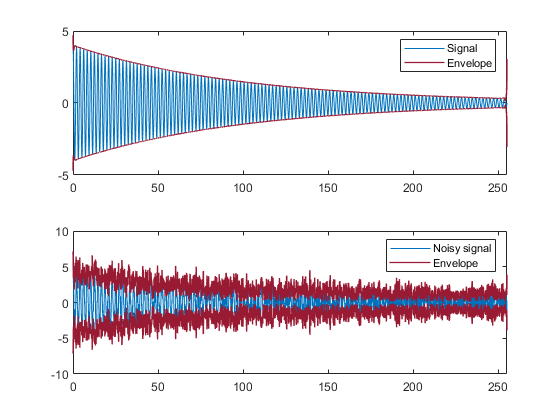

clear variables;

N = 256;
n = 0:0.1:N-1;
x = 4*exp(-0.01.*n).*cos(3*n);
plot_signal_and_envelope(n, x)

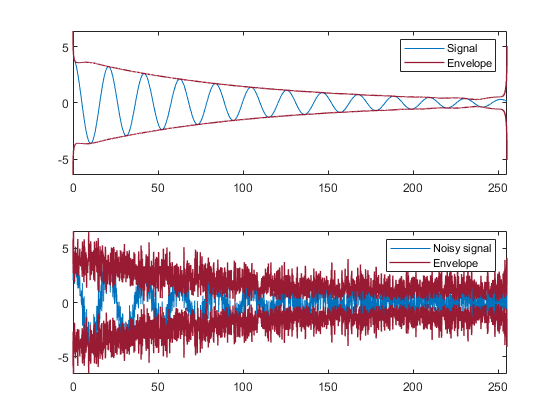

x = 4*exp(-0.01.*n).*cos(0.3*n);
plot_signal_and_envelope(n, x)

## [»] ADSI Problem 7.8: Amplitude modulated signal

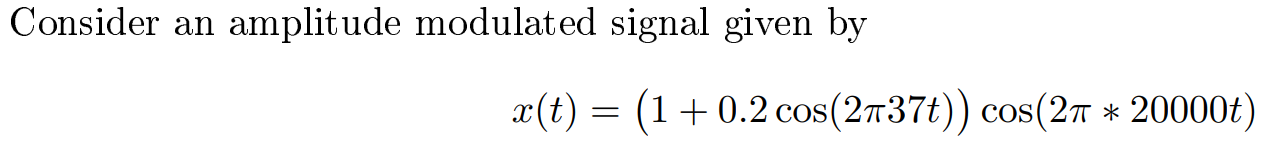

clear variables;

### [✔] 1. Plot 1 second of the signal and confirm that it is an amplitude modulated signal with a carrier frequency of 20 kHz.  

The discrete-time signal $x\left\lbrack n\right\rbrack$ of continuous-time signal $x\left(t\right)$ can be represented as:

        
$$x\left\lbrack n\right\rbrack =s\left(n\cdot T_s \right)$$
 

where 

- $n$ is an integer denoting the sample index 

- $T_s$ is the sampling period

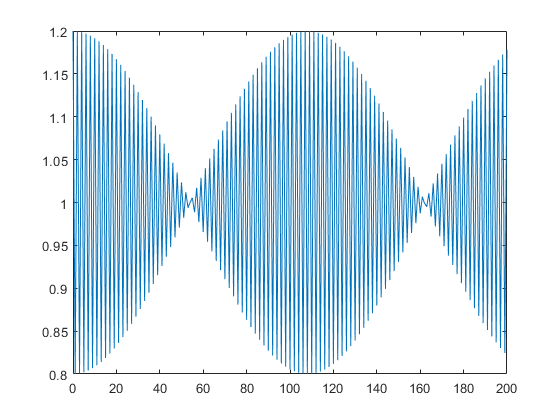

Ts = 8000; % Sampling rate
n = 0:200;
x = 1 + 0.2.*cos(2*pi*37*n/Ts).*cos(2*pi*20000*n/Ts);
plot(n, x)

### [»] 2. Use the procedure from Figure 9.8 in the note to frequency shift the signal to 15 kHz. Plot the spectrum of the signal at each step in the procedure.  

## Functions

function plot_signal_and_envelope(n, x)
w = randn(numel(n), 1)';
x_noisy = x + w;

x_c = hilbert(x);
x_envelope = abs(x_c);

x_noisy_c = hilbert(x_noisy);
x_noisy_envelope = abs(x_noisy_c);

clf
figure
ax1 = subplot(2,1,1);
plot(n, x)
hold on
plot(n, [-1;1]*x_envelope, 'Color', [0.6 0.1 0.2],'Linewidth',1)
hold off
legend('Signal', 'Envelope')
xlim([0, max(n)])

ax2 = subplot(2,1,2);
plot(n, x_noisy)
hold on
plot(n, [-1;1]*x_noisy_envelope, 'Color', [0.6 0.1 0.2],'Linewidth',1)
hold off
legend('Noisy signal', 'Envelope')
xlim([0, max(n)])
end